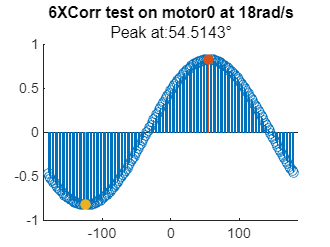

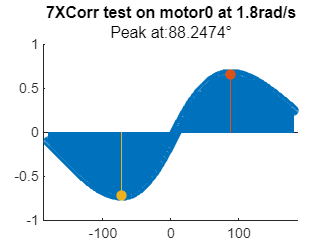

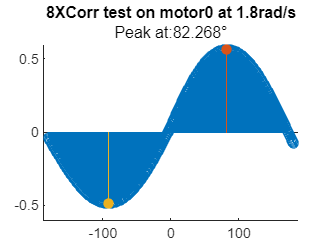

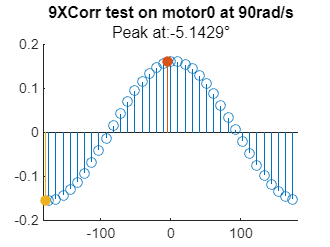

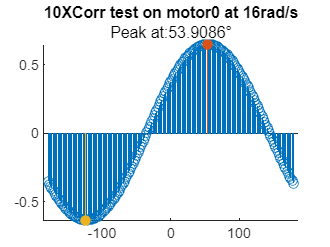

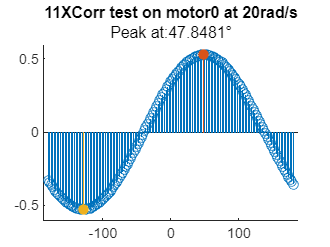

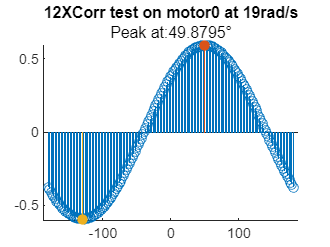

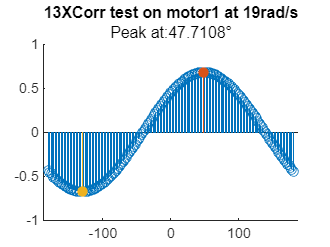

clear all;
filelist =["data_11-Mar-2025_14-37-46.mat" "data_11-Mar-2025_14-41-45.mat" "data_11-Mar-2025_15-16-40.mat" "data_11-Mar-2025_15-19-03.mat" "data_11-Mar-2025_15-40-23.mat" "data_11-Mar-2025_15-41-07.mat" "data_11-Mar-2025_15-52-28.mat" "data_11-Mar-2025_15-54-11.mat" "data_11-Mar-2025_15-59-13.mat" "data_11-Mar-2025_16-01-46.mat" "data_11-Mar-2025_16-03-02.mat" "data_11-Mar-2025_16-04-30.mat" "data_11-Mar-2025_16-06-17.mat" "data_11-Mar-2025_16-11-48.mat" "data_11-Mar-2025_16-13-05.mat" "data_11-Mar-2025_16-14-08.mat" "data_11-Mar-2025_16-15-13.mat" "data_11-Mar-2025_16-16-28.mat" "data_11-Mar-2025_16-17-45.mat" "data_11-Mar-2025_16-19-12.mat" "data_11-Mar-2025_16-22-06.mat" "data_11-Mar-2025_16-46-42.mat" "data_11-Mar-2025_16-49-20.mat" "data_11-Mar-2025_18-02-55.mat" "data_11-Mar-2025_18-09-05.mat" "data_11-Mar-2025_18-19-48.mat" "data_11-Mar-2025_18-21-25.mat" "data_11-Mar-2025_18-23-27.mat" "data_11-Mar-2025_18-24-00.mat" "data_11-Mar-2025_18-25-32.mat" "data_11-Mar-2025_18-26-22.mat" "data_11-Mar-2025_18-28-35.mat" "data_11-Mar-2025_18-29-53.mat" "data_11-Mar-2025_18-31-38.mat" "data_11-Mar-2025_18-34-32.mat" "data_11-Mar-2025_18-38-31.mat" "data_11-Mar-2025_18-40-21.mat" "data_11-Mar-2025_18-42-37.mat" "data_11-Mar-2025_18-43-54.mat" "data_11-Mar-2025_18-45-12.mat" "data_11-Mar-2025_18-47-03.mat" "data_11-Mar-2025_18-49-24.mat" ];
filetitle = "trash/lab2_"+string(datetime(now, 'ConvertFrom', 'datenum','Format','yyyy-MM-dd HH+mm+ss'));

goodID = [];
motor0 = [];
motor1 = [];

for idx = 1:(size(filelist,2))
    n_exp = idx; %filelist(idx);
    
    
    load("lab2/data/"+filelist(n_exp),"data");
    if size(data,1)>6
        
    
        if abs(data(4,2))>0
            motor_id = 0;
        else
            motor_id = 1;
        end
    
        t_sample = 0.002;
        omega = data(6,1);

        if omega < 0.5
            continue
        end

        period_signal = 2*pi/omega;
        max_samples_per_period = ceil(period_signal/t_sample);
        
        Amp = data(7,1);
        t_start = 1;
        t_start_idx = 1 +  t_start/t_sample;
        
        

        t = data(1,t_start_idx:end);
        if t_start_idx > size(t,2)
            continue
        end

        enc = data(2+motor_id,t_start_idx:end)*pi/2048;
        u = data(4+motor_id,t_start_idx:end);
        % 
        % plot(t,u)
        % title("Voltage signal")
        % plot(t,enc)
        % title("Encoder position")
        
        [c,lags] = xcorr(u,enc,floor(max_samples_per_period/2),'normalized');
        lags_angle = lags * 360/max_samples_per_period;
        [c_max, idx_max] = max(c);
        angle_max = -180 + (idx_max-1) * 360/max_samples_per_period;
        
        [c_min, idx_min] = min(c);
        angle_min = (idx_min-1) * 360/max_samples_per_period;
        
        
        figure
        hold on;
        stem(lags_angle,c)
        stem(angle_max,c_max,'filled')
        stem(-180+angle_min,c_min,'filled')
        
        
        phase_av = angle_max;
        hold off;
        title(n_exp + "XCorr test on motor"+motor_id+ " at "+omega+"rad/s")
        subtitle("Peak at:" + phase_av+"°")
        
        
        if motor_id == 0
            motor0(1,end+1) = phase_av;
            motor0(2,end) = omega;
        else
            motor1(1,end+1) = phase_av;
            motor1(2,end) = omega;
        end


        goodID(end+1) = idx;
    end

end

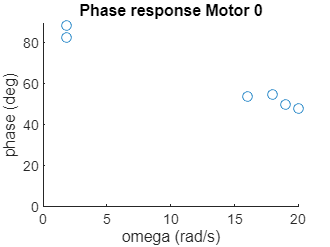

figure
scatter(motor0(2,:),motor0(1,:))
title("Phase response Motor 0")
xlabel("omega (rad/s)")
ylabel("phase (deg)")

ylim([0 90])

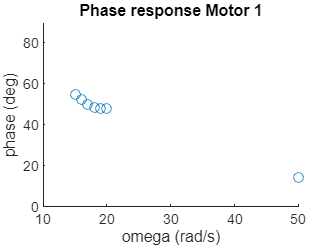

figure
scatter(motor1(2,:),motor1(1,:))
title("Phase response Motor 1")
xlabel("omega (rad/s)")
ylabel("phase (deg)")
ylim([0 90])